expmt.data.time

ans =   4807×1 RawDataField array with properties:

          raw: [4807×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/10-08/geo2, normal orientation/08-10-2021-14-12-40__Basic_Tracking_1-1_Day1/raw_data/08-10-2021-14-12-40__time.bin'
          fID: 4
          dim: [4807 1]
    precision: 'single'


reset(expmt.data.time)

ans =   4807×1 RawDataField array with properties:

          raw: [4807×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/10-08/geo2, normal orientation/08-10-2021-14-12-40__Basic_Tracking_1-1_Day1/raw_data/08-10-2021-14-12-40__time.bin'
          fID: 4
          dim: [4807 1]
    precision: 'single'


isattached(expmt.data.time)

ans = logical
   1



interframe_interval = expmt.data.time.raw();
t_elapsed = cumsum(interframe_interval);
% read all centroid data from file
reset(expmt.data.centroid);
centroids = expmt.data.centroid.raw();



%The code to wrangle tracking data in the first place...mostly from the
%MARGO website, and with some description of what's happening at each step
%to make it clear



%Let's plot every 1000th x,y coordinate for a single tracked fly

f = centroids(: , 1:2);
x = f(1:1000:end, 1)

x = 18×1 single column vector
       NaN
   42.9175
   43.6031
  190.7402
   95.1534
  253.2843
  154.1507
   31.0573
  106.0711
  315.3756


y = f(1:1000:end, 2)

y = 18×1 single column vector
       NaN
   49.7732
   42.8505
  157.8578
  782.5092
  211.7549
  554.1735
   25.8438
  338.2335
  539.3805


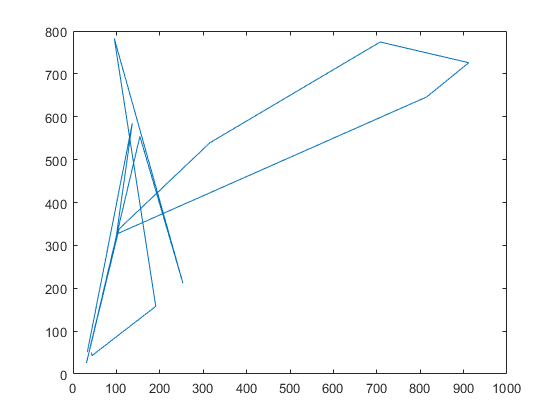


plot(x, y)

% This isn't quite right...the straight lines must reflect loss of signal
% in tracking. Maybe we need to remove all NANs from the plot? Not sure
% about this

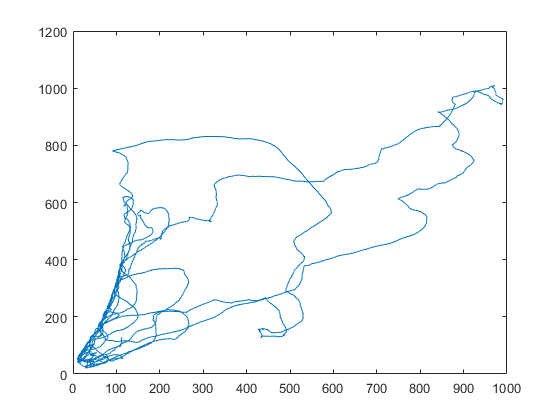

% Anyway, how about instead we plot the first hour of tracking. What does
% the time elapsed variable look like again? It's the cumsum of ifi. So
% ideally we would add it as a column in centroids

f = [f t_elapsed];

% What are the units of t_elapsed? Seconds. So the first hour of tracking
% is the number of seconds in an hour...3600. Let's plot the first hour for
% one fly

m_elapsed = t_elapsed/60;
h_elapsed = m_elapsed/60;

%I just checked and it's row 45566 where the first hour is complete. There
%must be a better way to do this. Anyway...

x = f(10:17999, 1);
y = f(10:17999, 2);

plot(x, y)


%This gives a nicer looking plot, and I guess I should be able to play it through
%like a video.

% How do I create the AI for each section of the experiment? How do I split
% the arena into 4 quadrants? The central point is about (1000,1000). Is
% there a way to specify a quadrant, say all points (x = (1000(mid) - Max), y =
% (1000(mid) - Max)) which would be in the upper right quadrant?

% I'm thinking about the range of coordinates that the flies use, but that
% is not the ROI coordinates...I should get those from the metadata using:

expmt.meta.roi

ans = struct with fields:
           mode: 'grid'
          shape: {'Quadrilateral'}
            vec: [1×4×2 double]
            row: 1
            col: 1
           grid: 1
        corners: [-0.0322 3.1611 1.0250e+03 1.0208e+03]
         bounds: [-0.0322 3.1611 1.0251e+03 1.0176e+03]
        centers: [512.5000 511.9678]
    orientation: 0
          tform: {[]}
             im: [1024×1024 uint8]
              n: 1
         pixIdx: {[1043456×1 double]}
           mask: [1024×1024 logical]
     num_traces: 6
       cam_dist: 723.7011


a = expmt.meta.roi

a = struct with fields:
           mode: 'grid'
          shape: {'Quadrilateral'}
            vec: [1×4×2 double]
            row: 1
            col: 1
           grid: 1
        corners: [-0.0322 3.1611 1.0250e+03 1.0208e+03]
         bounds: [-0.0322 3.1611 1.0251e+03 1.0176e+03]
        centers: [512.5000 511.9678]
    orientation: 0
          tform: {[]}
             im: [1024×1024 uint8]
              n: 1
         pixIdx: {[1043456×1 double]}
           mask: [1024×1024 logical]
     num_traces: 6
       cam_dist: 723.7011


xcentre = a.centers(1,1)

xcentre = 512.5000

ycentre = a.centers(1,2)

ycentre = 511.9678

%Took the following solution from: https://uk.mathworks.com/matlabcentral/answers/215004-determining-quadrants-in-a-matrix



out = num2cell(centroids, [1 2]); %split into cell array keeping dimensions 1 and 2 together
out = vertcat(out{:}) %concatenate all the cells vertically

x = out(:, 1);
y = out(:, 2);

out(x>xcentre & y>ycentre) = 1;
out(x<xcentre & y>ycentre) = 2;
out(x<xcentre & y<ycentre) = 3;
out(x>xcentre & y<ycentre) = 4;

x = out(:, 1);
y = out(:, 2);

out(x>561.9776 & y>561.9776,3) = 1;
out(x<461.9776 & y>561.9776,3) = 2;
out(x<461.9776 & y<461.9776,3) = 3;
out(x>561.9776 & y<461.9776,3) = 4;

out(x>461.9776 & x<561.9776,3) = 0; %
out(y>461.9776 & y<561.9776,3) = 0; %define middle cross which is not a part of any quadrant


%This seems to work, so now that we have these identifiers, we should be
%able to make an AI using the quadrant identifier. First, let's plot by
%quadrant identifier

%Convert to table
T = array2table(out);

%Remove NaNs
T=T(~any(ismissing(T),2),:);

gscatter(T.out1, T.out2, T.out3)


%Let's try to calculate AI per box. 

%From the Potter paper: An Attraction Index (AI) is defined as (Ot5-Cavgt5)/ (Ot5+Cavgt5), in which Ot5 is the number of tracked positional data points 
% in the odor quadrant and Cavgt5 is average number of tracked positional data points in non-odor control quadrants over a 5 min testing period. 

GC = groupcounts(T,'out3');

%Why are there any 0 values? Need to clear that up

Od = table2array(GC(2,2));
C1 = table2array(GC(4,2));
C2 = table2array(GC(3,2));
C3 = table2array(GC(5,2));
Con = (C1+C2+C3)/3

%Attraction Index - double check the implementation here. 
AI = (Od-Con)/(Od+Con);

%This code works, but it isn't great, and hardly easily reproducible.
%Ideally you'd write a small package with simple functions like, AI(),
%where you can specify over what time period etc. The other thing to
%consider is the introduction of optogenetics into the whole scheme. That
%will complicate things. 


%Attraction index for each quarter with cross
GC = groupcounts(T,'out3');
C1 = table2array(GC(2,2));
C2 = table2array(GC(3,2));
C3 = table2array(GC(4,2));
C4 = table2array(GC(5,2));
AI1 = (C1-(C2+C3+C4)/3)/(C1+(C2+C3+C4)/3);
AI2 = (C2-(C1+C3+C4)/3)/(C2+(C1+C3+C4)/3);
AI3 = (C3-(C2+C1+C4)/3)/(C3+(C2+C1+C4)/3);
AI4 = (C4-(C2+C3+C1)/3)/(C4+(C2+C3+C1)/3);



%Attraction index for each quarter, without cross
GC = groupcounts(T,'out3');
C1 = table2array(GC(1,2));
C2 = table2array(GC(2,2));
C3 = table2array(GC(3,2));
C4 = table2array(GC(4,2));
AI1 = (C1-(C2+C3+C4)/3)/(C1+(C2+C3+C4)/3);
AI2 = (C2-(C1+C3+C4)/3)/(C2+(C1+C3+C4)/3);
AI3 = (C3-(C2+C1+C4)/3)/(C3+(C2+C1+C4)/3);
AI4 = (C4-(C2+C3+C1)/3)/(C4+(C2+C3+C1)/3);

GC = groupcounts(T,'out3');
C1 = 0;
C2 = table2array(GC(2,2));
C3 = table2array(GC(3,2));
C4 = 0;
AI1 = (C1-(C2+C3+C4)/3)/(C1+(C2+C3+C4)/3);
AI2 = (C2-(C1+C3+C4)/3)/(C2+(C1+C3+C4)/3);
AI3 = (C3-(C2+C1+C4)/3)/(C3+(C2+C1+C4)/3);
AI4 = (C4-(C2+C3+C1)/3)/(C4+(C2+C3+C1)/3);
